**Clustering problem - k-means algorithm**

Consider the k-means algorithm, with k = 3, for the set of patterns given.

a) Run the algorithm starting from centroids x1 = (5, 7), x2 = (6, 3), x3 = (4, 3). 

b) Run the algorithm starting from centroids x1 = (5, 7), x2 = (6, 3), x3 = (4, 4). 

close all; 
clear; 
clc;

matlab.lang.OnOffSwitchState = 1;

global data l;

data = [1.2734    6.2721
        2.7453    7.4345
        1.6954    8.6408
        1.1044    8.6364
        4.8187    7.3664
        2.7224    6.3303
        4.8462    8.4123
        4.0497    6.7696
        1.0294    8.6174
        3.7202    5.1327
        3.8238    7.1297
        3.5805    7.8660
        3.2092    5.7172
        1.8724    6.3461
        4.0895    5.7509
        1.9121    6.2877
        2.4835    6.6154
        4.5637    7.1943
        4.4255    5.1950
        2.6097    7.2109
        6.0992    8.0496
        5.9660    7.3042
        5.9726    7.9907
        5.6166    7.5821
        8.8257    5.4929
        8.7426    7.0176
        8.2749    6.3890
        7.9130    5.3686
        5.7032    5.5914
        6.4415    5.7927
        5.7552    7.6891
        5.0048    6.7260
        6.2657    7.7776
        7.7985    6.0271
        7.5010    5.0390
        7.1722    7.1291
        6.7561    6.1176
        6.1497    8.7849
        7.0066    8.6258
        8.0462    6.5707
        3.0994    1.7722
        5.6857    2.3666
        6.3487    4.7316
        6.8860    2.5627
        3.2277    2.0929
        4.8013    1.6078
        5.3299    2.5884
        5.7466    2.4989
        5.8777    1.5245
        5.6002    2.7402
        5.9077    1.3661
        4.4954    3.4585
        5.3263    1.0439
        3.4645    3.2930
        3.2306    4.1589
        6.9191    1.9415
        4.1393    2.7921
        5.3799    3.2774
        6.8486    1.2456
        3.7431    2.9852];

% number of patterns
l = size(data, 1); 
k = 3;

% initialize centroids
x = [5 7
     6 3 
     4 3];  % part a)

fprintf("Exercise A. Centroids \n");

Exercise A. Centroids 


for i = 1:k
    fprintf("%.2f %.2f \n", x(i, 1), x(i, 2));
end

5.00 7.00 
6.00 3.00 
4.00 3.00 


v = 263.0261

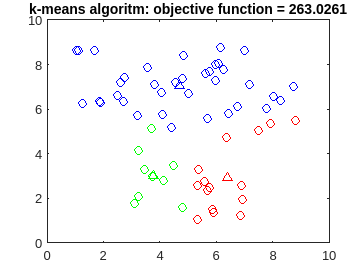

exercise_kmeans(x, k);


x = [5 7
     6 3
     4 4];  % part b)

fprintf("Exercise B. Centroids \n");

Exercise B. Centroids 


for i = 1:k
    fprintf("%.2f %.2f \n", x(i, 1), x(i, 2));
end

5.00 7.00 
6.00 3.00 
4.00 4.00 


v = 147.8304

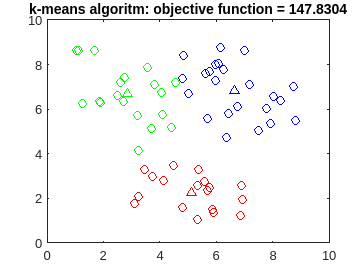

exercise_kmeans(x, k);

c) Is it possible to improve the solutions obtained in a) and b)?

vbest = inf;
xbest = [];
clusterbest = [];
maxiter = 100;
iter = 0;


while iter < maxiter
    InitialCentroids = 10*rand(k,2);
    [best,bestcluster,v, D] = kmeans(data,k,'Start',InitialCentroids);
    if v < vbest
        xbest = best;
        clusterbest = bestcluster;
        vbest = v
    end
    iter = iter + 1;
end

vbest =    48.7193
   57.1444
   41.6245



fprintf("Exercise C. Centroids \n");

Exercise C. Centroids 


for i = 1:k
    fprintf("%.2f %.2f \n", clusterbest(i, 1), clusterbest(i, 2));
end

6.92 6.75 
3.12 6.94 
5.04 2.39 


v = 147.4882

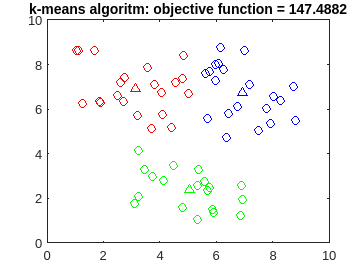

exercise_kmeans(clusterbest, k);

function exercise_kmeans(centroid, k)
    global data l;
    % plot patterns
    plot(data(:,1),data(:,2),'ko');
    axis([0 10 0 10])
    title('k-means algorithm');
    hold on
    
    x = centroid;
    % plot centroids
    plot(x(1,1),x(1,2),'b^',...
        x(2,1),x(2,2),'r^',...
        x(3,1),x(3,2),'g^');
    
    pause
    
    % initialize clusters
    cluster = zeros(l,1);
    for i = 1 : l
        d = inf;
        for j = 1 : k
            if norm(data(i,:)-x(j,:)) < d
                d = norm(data(i,:)-x(j,:));
                cluster(i) = j;
            end
        end
    end
    
    % plot cluster
    c1 = data(cluster==1,:);
    c2 = data(cluster==2,:);
    c3 = data(cluster==3,:);
    plot(c1(:,1),c1(:,2),'bo',c2(:,1),c2(:,2),'ro',...
        c3(:,1),c3(:,2),'go');
    
    % compute the objective function value
    v = 0;
    for i = 1 : l
        v = v + norm(data(i,:)-x(cluster(i),:))^2 ;
    end
    title(['k-means algoritm: objective function = ',num2str(v)]);
    
    pause
    
    while true
        
        % delete old centroids
        plot(x(1,1),x(1,2),'w^',...
            x(2,1),x(2,2),'w^',...
            x(3,1),x(3,2),'w^');
        
        % update centroids
        for j = 1 : k
            ind = find(cluster == j);
            if ~isempty(ind)
                x(j,:) = mean(data(ind,:));
            end
        end
        
        % plot new centroids
        plot(x(1,1),x(1,2),'b^',...
            x(2,1),x(2,2),'r^',...
            x(3,1),x(3,2),'g^');
        
        pause
        
        % update clusters
        for i = 1 : l
            d = inf;
            for j = 1 : k
                if norm(data(i,:)-x(j,:)) < d
                    d = norm(data(i,:)-x(j,:));
                    cluster(i) = j;
                end
            end
        end
        
        % plot cluster
        c1 = data(cluster==1,:);
        c2 = data(cluster==2,:);
        c3 = data(cluster==3,:);
        plot(c1(:,1),c1(:,2),'bo',c2(:,1),c2(:,2),...
            'ro',c3(:,1),c3(:,2),'go');
        
        
        % update objective function
        vnew = 0;
        for i = 1 : l
            vnew = vnew + norm(data(i,:)-x(cluster(i),:))^2 ;
        end
        title(['k-means algoritm: objective function = ',num2str(vnew)]);
    
        pause
        
        % stopping criterion
        if v - vnew < 1e-5
            break
        else
            v = vnew;
        end
        
    end
    
    v
    hold off

end